# 6. Considere a cadeia de Markov com o diagrama de transicao de estados seguinte:

## a) Defina em Matlab a matriz de transicao de estados T, com Tij sendo a probabilidade de ir do estado j para o estado i num unico passo.

%   1 2 3 4 5
%  1
%  2
%  3
%  4
%  5

T = [0.8 0 0 0.3 0
    0.2 0.6 0 0.2 0
    0 0.3 1 0 0
    0 0.1 0 0.4 0
    0 0 0 0.1 1];


## b) Faca um grafico com a probabilidade de comecando no estado 1, estar no estado 2 ao fim de n passos, com n a variar de 1 ate 100. Justifique o que observa.

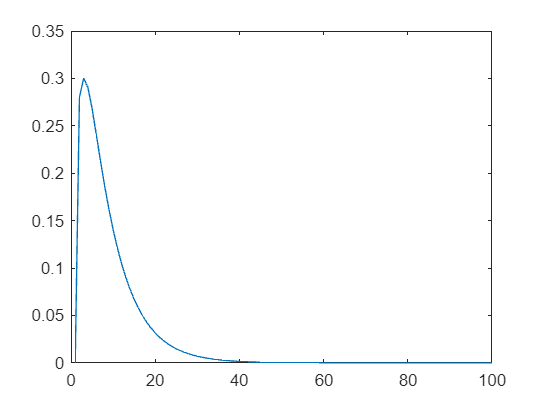

inicial = [1 0 0 0 0]';
probs = zeros(1, 100);
probs(1) = 0;
for i=2:100
    p = T^i*inicial;
    probs(i) = p(2);
end
plot(probs);

## c) Faca um grafico com a probabilidade de, comecando no estado 1, estar no estado 3 ao fim de n passos. Na mesma figura, faca um segundo grafico com a probabilidade de, comecando no estado 1, estar no estado 5 ao fim de n passos. Em ambos os casos, considere n a variar de 1 ate 100. Justifique o que observa.

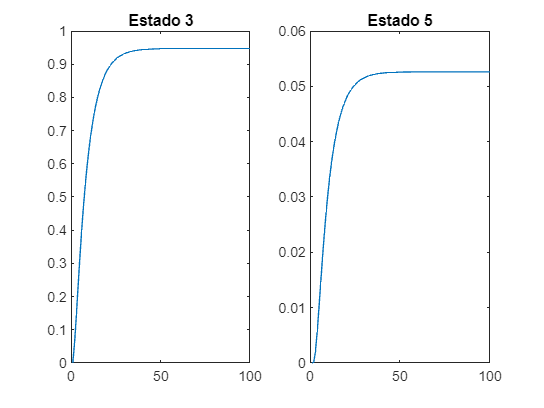

inicial = [1 0 0 0 0]';
probs_3 = zeros(1, 100);
probs_5 = zeros(1, 100);
probs_3(1) = 0;
probs_5(1) = 0;
for i=2:100
    p = T^i*inicial;
    probs_3(i) = p(3);
    probs_5(i) = p(5);
end

figure(2)
subplot(1,2,1)
plot(probs_3)
title('Estado 3')
subplot(1,2,2)
plot(probs_5)
title('Estado 5')

%Como os estados sao absorventes, à medida que há passagem de estados a
%probabilidade de estar num estado absorvente tende para 1


## d) Determine a matriz Q.

% Matriz de estados canonica
%    1    2    4  3 5
C = [0.8 0   0.3  0 0
     0.2 0.6 0.2  0 0
     0   0.1 0.4  1 0
     0   0.3 0    0 0
     0   0   0.1  0 1]

C =     0.8000         0    0.3000         0         0
    0.2000    0.6000    0.2000         0         0
         0    0.1000    0.4000    1.0000         0
         0    0.3000         0         0         0
         0         0    0.1000         0    1.0000


sum(C);
Q = C(1:3, 1:3) %buscar a linha de 1-3 de C e coluna de 1-3 de C

Q =     0.8000         0    0.3000
    0.2000    0.6000    0.2000
         0    0.1000    0.4000
